# Stellar Motion

In this project, we will be examining the light from stars and find the shift in hydrogen spectrum to calculate the speed of the star relative to Earth.

The star spectrum data in the `spectra` (excel sheet) matrix was collected at evenly spaced wavelengths ($\lambda$) , and we are given the starting wavelength ($\lambda_{\textrm{start}}$), the spacing ($\lambda_{\textrm{delta}}$), and the number of observations (all in the starData file).

Each column of `spectra` is the spectrum of a different star. The sixth column is the spectrum of star HD 94028.

This code loads the data and defines measurement parameters.

load starData.mat  %Loads data in the matlab file defined/written earlier 
spectra = table2array(spectra) %converts the table in the file to an array

spectra = 1.0e-12 *

    0.3088    0.1340    0.0598    0.0892    0.1088    0.1625    0.0392
    0.3136    0.1338    0.0607    0.0898    0.1084    0.1630    0.0382
    0.3105    0.1347    0.0618    0.0915    0.1104    0.1615    0.0371
    0.3076    0.1357    0.0625    0.0931    0.1124    0.1586    0.0378
    0.3088    0.1354    0.0627    0.0936    0.1122    0.1574    0.0391
    0.3105    0.1343    0.0622    0.0932    0.1136    0.1589    0.0396
    0.3122    0.1335    0.0619    0.0929    0.1138    0.1611    0.0402
    0.3101    0.1325    0.0620    0.0925    0.1130    0.1607    0.0399
    0.3078    0.1335    0.0626    0.0924    0.1124    0.1593    0.0387
    0.3047    0.1329    0.0625    0.0918    0.1108    0.1582    0.0379


We will create a variable named `lambdaEnd` (${\lambda}_{end}$) that contains the value of the last wavelength in the recorded spectrum. You can calculate `lambdaEnd` with the expression ${\lambda}_{start} + (nObs -1){\lambda}_{delta}$.

We use `lambdaEnd` to create a vector named `lambda(`$\lambda$) that contains the wavelengths in the spectrum, from ($\lambda_{\mathrm{start}}$), in steps of $\lambda_{\mathrm{delta}}$.

lambdaEnd = lambdaStart+(nObs-1)*lambdaDelta  %Calculating lambdaEnd as per formula

lambdaEnd = 679.8600

lambda = lambdaStart:lambdaDelta:lambdaEnd   %Making the vector lambda as per specifications

lambda =   630.0200  630.1600  630.3000  630.4400  630.5800  630.7200  630.8600  631.0000  631.1400  631.2800  631.4200  631.5600  631.7000  631.8400  631.9800  632.1200  632.2600  632.4000  632.5400  632.6800  632.8200  632.9600  633.1000  633.2400  633.3800  633.5200  633.6600  633.8000  633.9400  634.0800  634.2200  634.3600  634.5000  634.6400  634.7800  634.9200  635.0600  635.2000  635.3400  635.4800  635.6200  635.7600  635.9000  636.0400  636.1800  636.3200  636.4600  636.6000  636.7400  636.8800


We will be working with the star HD 94028 whose spectra is in the 6th column of the table spectra. So, we will extract the 6th column from the table and store it in s.

%s = spectra(:,6)
s = spectra(:,6) %This slider heps navigate and view all data

s = 1.0e-12 *

    0.1625
    0.1630
    0.1615
    0.1586
    0.1574
    0.1589
    0.1611
    0.1607
    0.1593
    0.1582


%simulatneously and easily. Comment in the above line and comment out this
%one to use it.

We will now plot s (spectra/stellar intensity of HD94028) vs wavelength and label the axes appropriately.

hold on %This signifies that all commands until hold off are for the same graph
plot(lambda,s,".-") %Plot lambda on x-axis, s on y-axis and use dots(.) to denote data points & use a continuous line(-)
xlabel Wavelegth
ylabel Intensity
hold off %This signifies the end of the hold block, any new plots won't be added to this unless hold is turned on again

This graph shows a dip in the spectra at around 657nm. This dip corresponds to the $\alpha$ line in the Hydrogen emission spectrum. 

To get the value of intensity at this dip and the exact wavelength at which it occurs, we use the min function. recall that min function can have two outputs; one corresponds to the minimum value and the other one corresponds to the index/value at which occurs.

But there're a few things we need to keepin mind and account for:

- s is a vector of intensities. Intensities are not of any particular interest in this analysis.

- The index in s starts from fro 1; not 630.02 i.e. the index we get from the min function is not of any use at it's face value.

We need to get the wavelength at that particular index. We can do this by getting the value from the lambda vector at the min index.

[sHa, idx] = min(s) %First value is the min value and the second value is the index

sHa = 9.8010e-14

idx = 191

lambdaHa = lambda(idx)  %Find the corresponding value of lambda at the index of minimum intensity.

lambdaHa = 656.6200

The point (lambdaHa, sHa) is the location of Hydrogen-$\alpha$ line. We now mark it with a red square of marker size 8.

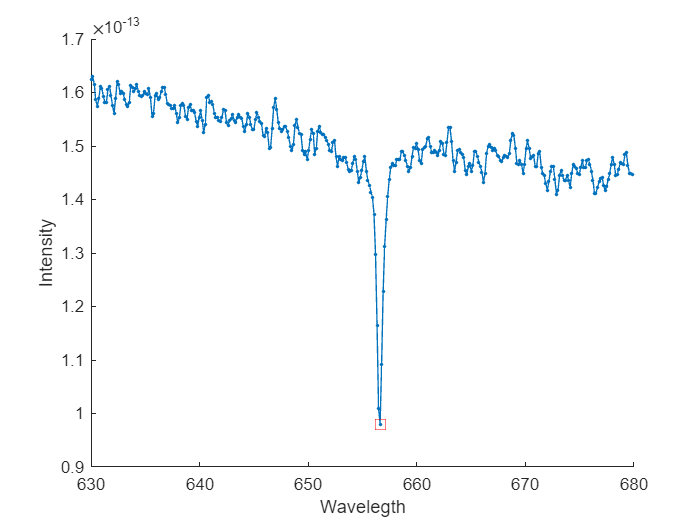

hold on
plot(lambdaHa,sHa,"rs","MarkerSize",8) %r - red, s - square, MarkerSize - point parameter, 8 - size
hold off

A close inspection at the Hydrogen-$\alpha$ point obtained reveals that the wavelength of the hydrogen-alpha line of HD 94028 is 656.62 nm, which is slightly longer than the laboratory value of 656.28 nm.

This is because of the motion of the star relative to Earth. This phenomenon is called the Doppler effect for light which is similar to the doppler effect for sound. The increase in wavelength implies that the star is moving away from Earth.

The exact velocity can be obatained (to first order aproximation) from the following relations:


$$z=\frac{\lambda_{\mathrm{obtained}} }{\lambda_{\mathrm{ideal}} }-1$$



$$z=\frac{v}{c}$$


where z = Redshift factor,

$\lambda_{\mathrm{obtained}}$ = Wavelength of light measured with redshift

$\lambda_{\mathrm{ideal}}$ = Wavelength of light without any redshift corresponding to the above wavelength

$v$ = Speed of the star

$c$ = Speed of light (=299792.458 km/s)

Because we know where the H-$\alpha$ should be and where the H-$\alpha$ actually is (i.e. we know the obtained wavelength and the corresponding actual wavelength), as $\lambda_{\mathrm{obtained}}$ = 656.62 and $\lambda_{\mathrm{ideal}}$ = 656.28, we can obtain the speed of star relative to Earth.

z = lambdaHa/656.28 - 1

z = 5.1807e-04

v = z*299792.458

v = 155.3139